# SNW_VFI_PARAM Tiny Solution Analysis Consumption Rule Changes

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**snw_vfi_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_vfi_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function analyzes the effects of the consumption allocation rule on model choices. The consumption allocation rule could be such that been married and having children does not change contemperaneous utility, only changes income. 

- Household consumption is within household public good. Having children and been married only impacts income

- Marginal utility of household consumption is higher when there are more kids and given marriage with uniform division of consumption for each household member, and the household planner cares about household consumption divided by the number of individuals in the household

- Consumption divide by square root of household member count. 

## Public Good: Test SNW_VFI_MAIN Tiny with cons_allocation_rule = 0 

Call the function with defaults.

mp_param = snw_mp_param('default_tiny');
mp_param('cons_allocation_rule') = 0

mp_param =   Map with properties:

        Count: 28
      KeyType: char
    ValueType: any


[V_VFI_car0,ap_VFI_car0,cons_VFI_car0,exitflag_VFI_car0] = snw_vfi_main(mp_param);

## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_grid = mp_param('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 3; % how many shock legends to show
mp_support_graph('st_rounding') = '6.2f'; % format shock legend

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_shock__1_4213    mean_shock__0_71067    mean_shock_0    mean_shock_0_71067    mean_shock_1_4213
    _____    ________    __________________    ___________________    ____________    __________________    _________________

      1             0         -9.1873                 -6.009             -3.7436           -2.0125              -0.98325     
      2      0.068587         -6.6163                -4.6098             -2.7634           -1.2296              -0.27233     
      3        0.5487         -1.2832               -0.84937            -0.33053           0.30289               0.96385     
      4        1.8519          1.0089                 1.0907              1.2155  

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_shock__1_4213    mean_shock__0_71067    mean_shock_0    mean_shock_0_71067    mean_shock_1_4213
    _____    ________    __________________    ___________________    ____________    __________________    _________________

      1             0         0.012427              0.036775            0.095255           0.21431               0.49029     
      2      0.068587         0.046044              0.073485             0.15988            0.2646               0.52478     
      3        0.5487          0.38016                0.3815             0.43301           0.64172               0.91251     
      4        1.8519           1.3152                 1.321              1.3374   

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_shock__1_4213    mean_shock__0_71067    mean_shock_0    mean_shock_0_71067    mean_shock_1_4213
    _____    ________    __________________    ___________________    ____________    __________________    _________________

      1             0         0.21269                 0.2688             0.3677            0.56194               0.91651     
      2      0.068587         0.29421                0.34667            0.41729            0.62565               0.99593     
      3        0.5487         0.75896                0.83603            0.94019             1.0437                1.4028     
      4        1.8519          1.9776                 2.0495              2.188     

Graph Mean Values:

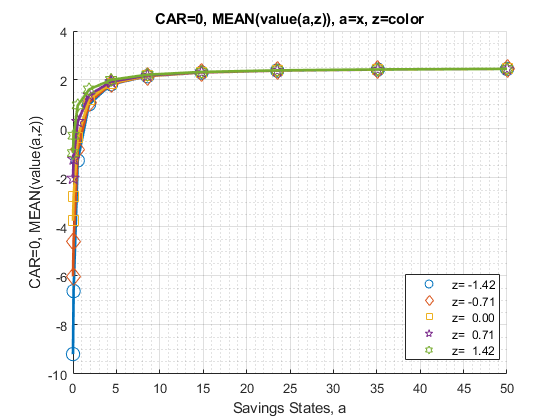

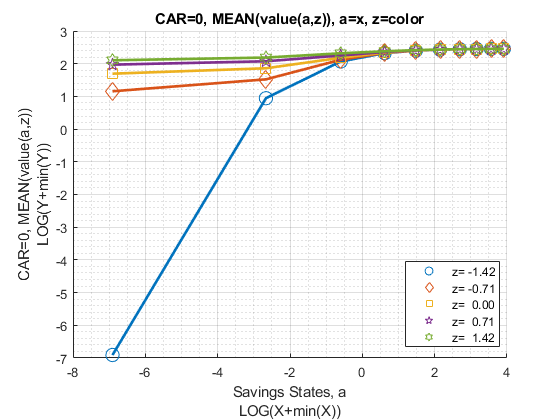

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

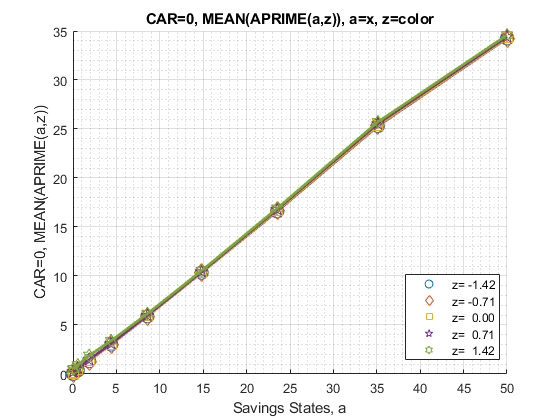

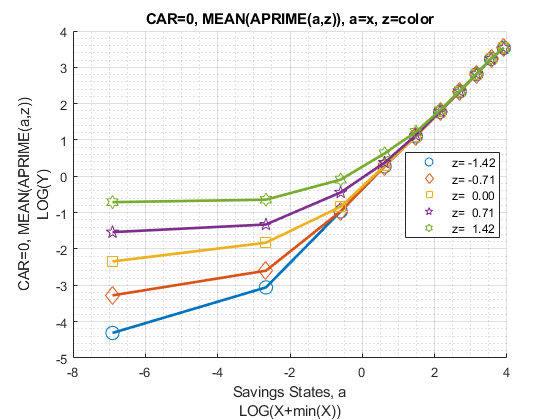

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Consumption:

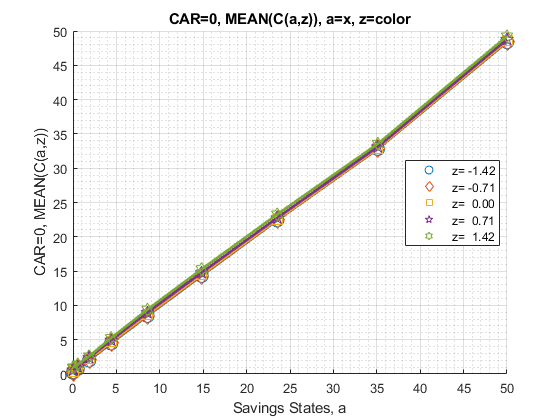

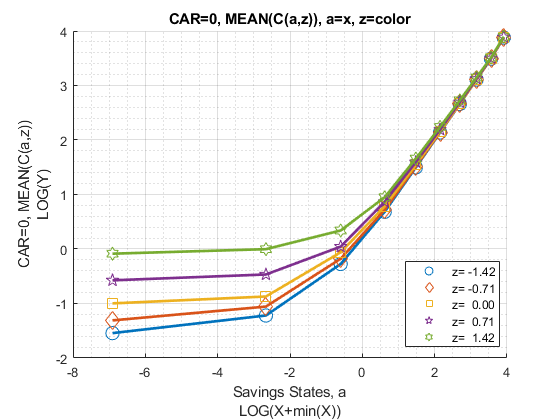

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", V_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        1.2183         1.0484         0.89246        0.54373       -0.081039      0.071957         0.1007   
      2       2        0        1.2183         1.0484         0.89246        0.54373       -0.081039      0.071957         0.1007   
      3       3        0        1.2183         1.0484         0.89246        

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0         15.06         14.347         14.036         13.561         9.0925         2.7263            0      
      2       2        0         15.06         14.347         14.036         13.561         9.0925         2.7263            0      
      3       3        0         15.06         14.347         14.036         1

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        8.5784         9.2918         9.8348         10.279         14.031         20.397          23.124   
      2       2        0        8.5784         9.2918         9.8348         10.279         14.031         20.397          23.124   
      3       3        0        8.5784         9.2918         9.8348         10

Graph Mean Values:

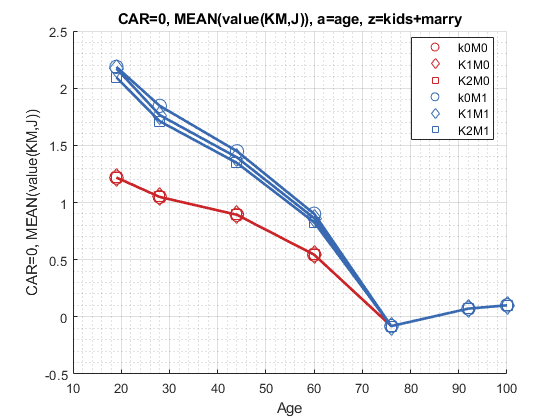

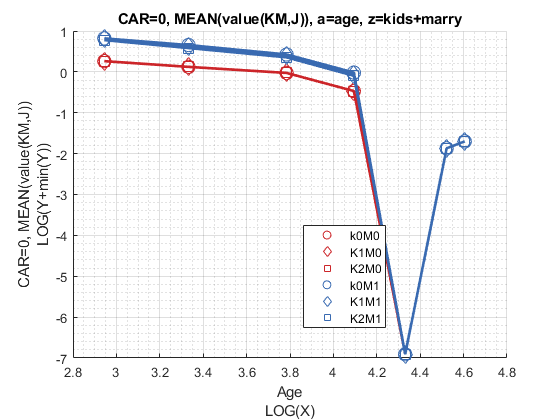

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

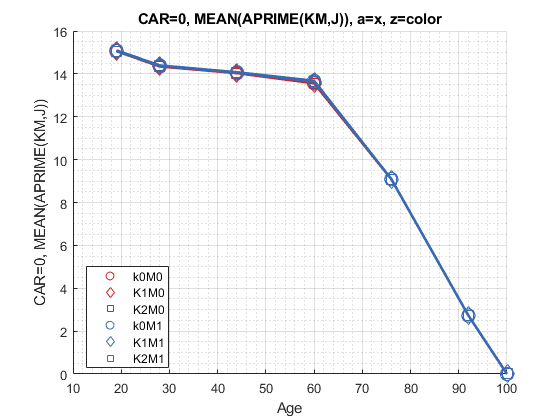

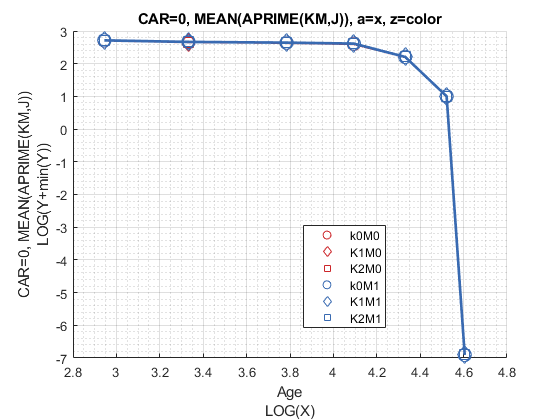

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

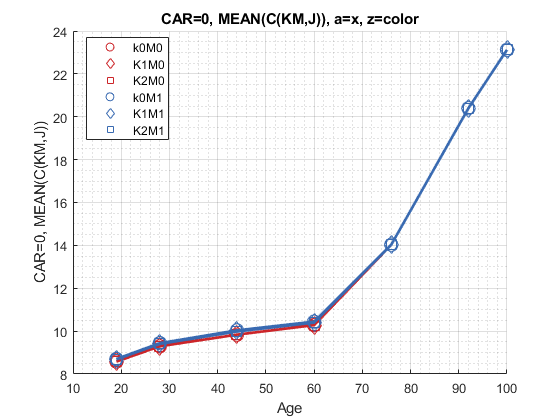

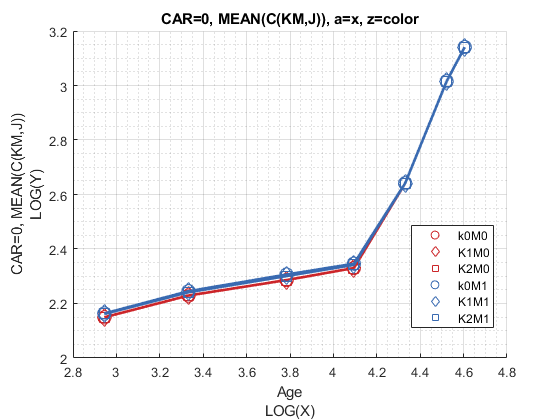

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        0.88385        0.76163        0.65943        0.37834       -0.18248        0.01172        0.044241  
      2       1       0         1.5527         1.3352         1.1255        0.70912       0.020403        0.13219         0.15715  
      3       0       1         1.9094         1.5642         1.2234        0.73

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        15.043          14.34         13.994         13.508         9.0967         2.7361            0      
      2       1       0        15.077         14.354         14.077         13.614         9.0883         2.7165            0      
      3       0       1        15.059         14.372          14.02         13.58

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        8.5074         9.2108         9.7136         10.185         14.009         20.369          23.106   
      2       1       0        8.6495         9.3729         9.9561         10.373         14.054         20.425          23.142   
      3       0       1        8.6094         9.3248         9.8669         10.314

Graph Mean Values:

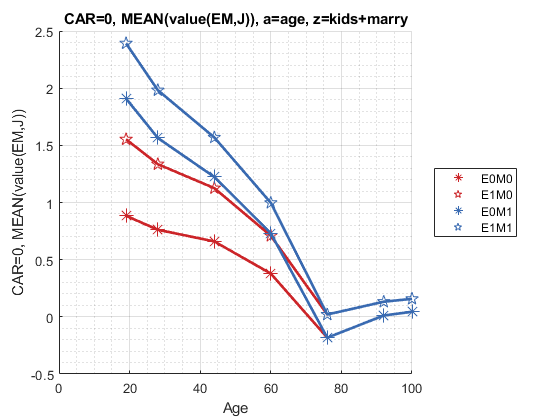

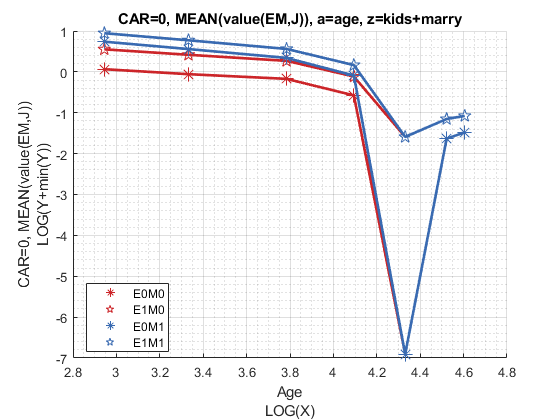

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

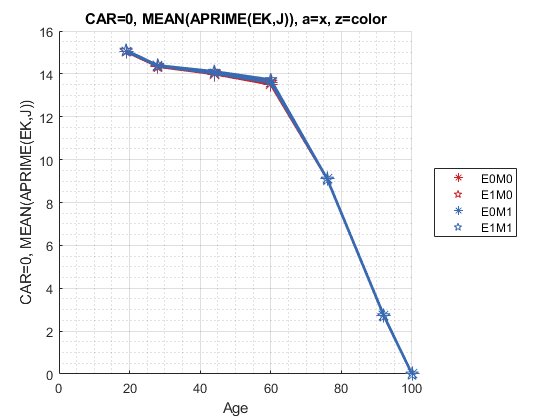

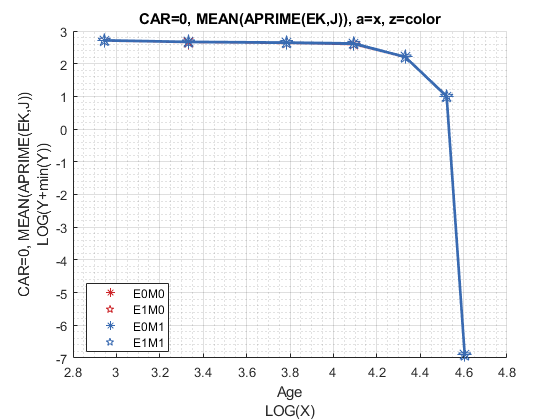

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

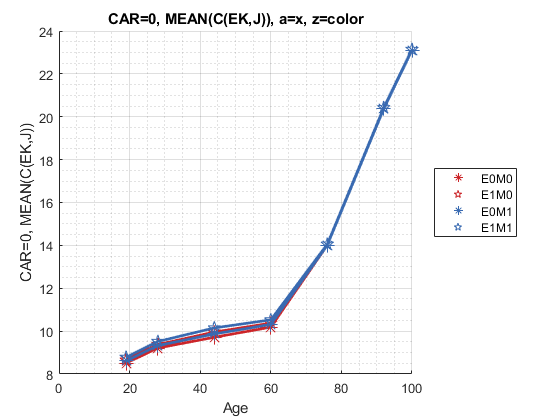

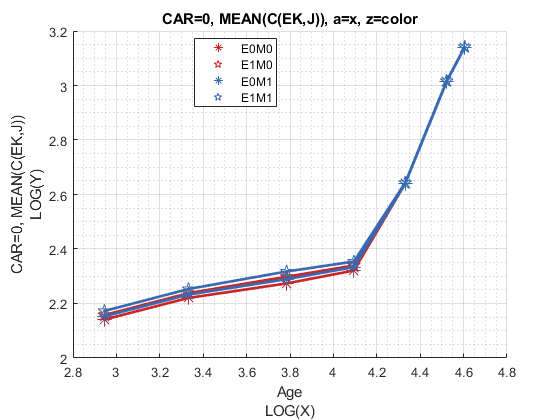

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);